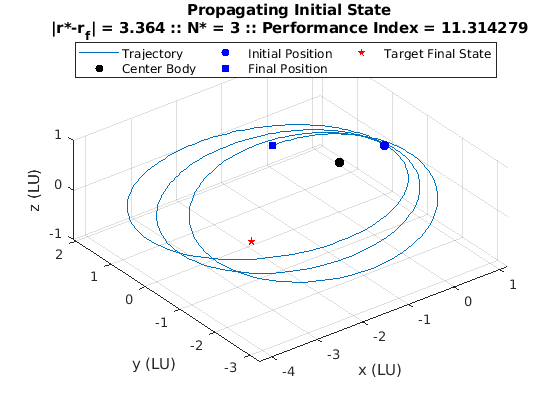

clear; clc
% SETTING INPUTS
global EoM cost
J2 = 0.1;
R = 0.9;
mu = 1;
ToF = 83;
N = 3;
r0 = [1 0 0].';
rf = [-2.891216226058043 -1.254145998446107 0].';
cost = @(rstar, Nstar) (rstar - rf).' * (rstar - rf) + 1e10 * (N - Nstar)^2;

% INITIAL GUESS
ICnum = 1;
v0 = [0.05 1.305 0;
      -0.2 1.27 0];
v0 = v0(ICnum, :).';

% FINDING EOMs
syms x y z
F1 = x^2 + y^2 + z^2;
U = mu/sqrt(F1) * (1 - R^2/F1 * J2 * ((3*z^2)/(2*F1) - 1/2));
rddot = matlabFunction([diff(U, x); diff(U, y); diff(U, z)]);
EoM = @(t, y) [y(4:6); rddot(y(1), y(2), y(3))];

% TEST PROPAGATING
opts = odeset('RelTol', 1e-6, 'AbsTol', 1e-6, 'Events', @eventFcn);
[t, Y, te, ye, ie] = ode45(EoM, [0 ToF], [r0; v0], opts);
Nstar = length(te) - 1;
rstar = Y(end, 1:3).';

% INTERPRETTING
plot3(Y(:, 1), Y(:, 2), Y(:, 3), 'DisplayName', 'Trajectory')
grid on
axis equal
hold on
scatter3(0, 0, 0, 50, 'ko', 'filled', 'DisplayName', 'Center Body')
scatter3(Y(1, 1), Y(1, 2), Y(1, 3), 50, 'bo', 'filled', 'DisplayName', 'Initial Position')
scatter3(Y(end, 1), Y(end, 2), Y(end, 3), 50, 'bs', 'filled', 'DisplayName', 'Final Position')
scatter3(rf(1), rf(2), rf(3), 50, 'rp', 'filled', 'DisplayName', 'Target Final State')
hold off
xlabel('x (LU)'); ylabel('y (LU)'); zlabel('z (LU)');
title(sprintf('Propagating Initial State\n|r*-r_f| = %0.4g :: N* = %i :: Performance Index = %0.8g', norm(rstar - rf), Nstar, cost(rstar, Nstar)))
legend('Location','north', 'NumColumns',3)
exportgraphics(gcf, sprintf('hw3p4_%i_Initial.png', ICnum), 'Resolution', 200);

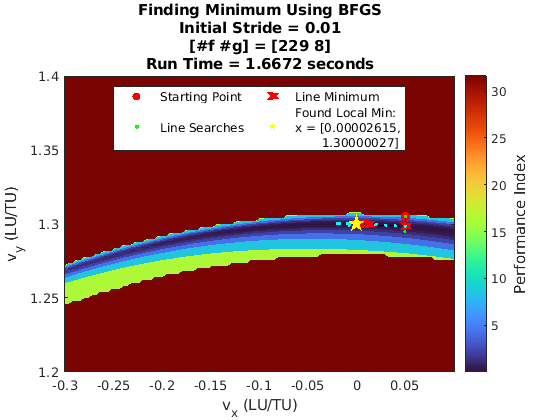


% CREATING CALLS FOR MINIMIZATION
func = @(x) propWithCost(x, r0, ToF); func(v0);
grad = @(x) costGradient(x, r0, ToF); grad(v0);

% ITERATION SETUP
dx = Inf;
i = 0;
fCalls = [0 0 0];
x = v0;
t0 = 0.01;

% ITERATING
tic
while dx > 1e-8
    i = i+1;
    % FINDING DIRECTION
    if i == 1; dir0 = []; else; dir0 = dir(i-1); end
    dir(i) = BFGS(x, grad, dir0); % Broyden-Fletcher-Goldfarb-Shanno
    s = dir(i).s;
    fCalls = fCalls + dir(i).fCalls;
    
    % LINE SEARCHING
    lin(i) = lineSearch(x, s, func, t0, 4, 2);
    fCalls = fCalls + lin(i).fCalls;
    
    % MINIMIZING
    mini(i) = grMin([lin(i).pts(:).x], func);
    fCalls = fCalls + mini(i).fCalls;
    
    % ALIGNING NEW MINIMUM
    %     if norm(x - mini(i).xmin) < 1e-8; warning('WARNING: dx = 0'); break; end
    dx = norm(x - mini(i).xmin);
    x = mini(i).xmin;
%     grad = f_grad(x);
%     fCalls(2) = fCalls(2) + 1;
    if i == 1000; break; end
end
time = toc;

% PLOTTING PATH
% Contour
load hw4p4.mat
contourf(x1_space, x2_space, z_space, [logspace(-4, 1.5, 20)], ...
    'HandleVisibility',"off", 'LineStyle',"none")
colormap turbo
hold on

% Start Point
scatter(v0(1), v0(2), 50, 'ro', 'filled', 'DisplayName', 'Starting Point')
stringMin = cat(2, v0, [mini(:).xmin]); 
plot(stringMin(1, :), stringMin(2, :), 'k--', 'HandleVisibility',"off")

% Creating Initial Plots and Legend Entries
x = lin(1).allPts;
scatter(x(1, :), x(2, :), 20, 'g.', 'DisplayName', 'Line Searches')
xmin = mini(1).xmin;
scatter(xmin(1), xmin(2), 30, 'rx', 'DisplayName', 'Line Minimum', 'linewidth', 5)

% Rest of Line Searches
l = length(lin); if l > 100; l = 100; end
for i = 2:l
    % Line Searches
    x = lin(i).allPts;
    scatter(x(1, :), x(2, :), 20, 'c.', 'HandleVisibility', 'off')
end
for i = 2:l
    % Minimums
    xmin = mini(i).xmin;
    scatter(xmin(1), xmin(2), 30, 'rx', 'HandleVisibility', 'off', 'linewidth', 5)
end

% Final Point
scatter(xmin(1), xmin(2), 200, 'yp', 'filled', 'linewidth', 1, ...
    'DisplayName', sprintf('Found Local Min:\nx = [%0.8f,\n       %0.8f]', xmin(1), xmin(2)))
hold off
legend('Location','north', 'NumColumns',2)
C = colorbar;
C.Label.String = 'Performance Index';
C.Label.FontSize = 11;
xlabel('v_x (LU/TU)'); ylabel('v_y (LU/TU)')
title(sprintf('Finding Minimum Using BFGS\nInitial Stride = %0.3g\n[#f #g] = [%i %i]\nRun Time = %0.5g seconds', t0, fCalls(1), fCalls(2), time))
exportgraphics(gcf, sprintf('hw3p4_%i_MinSearch.png', ICnum), 'Resolution', 200);

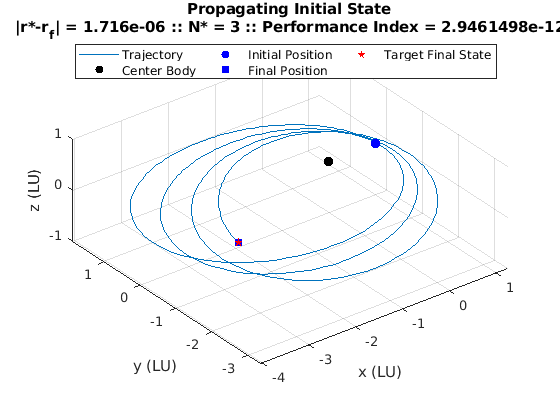


% PROPAGATING FOUND SOLUTION
opts = odeset('RelTol', 1e-6, 'AbsTol', 1e-6, 'Events', @eventFcn);
[t, Y, te, ye, ie] = ode45(EoM, [0 ToF], [r0; mini(i).xmin], opts);
Nstar = length(te) - 1;
rstar = Y(end, 1:3).';

% PLOTTING SOLUTION
plot3(Y(:, 1), Y(:, 2), Y(:, 3), 'DisplayName', 'Trajectory')
grid on
axis equal
hold on
scatter3(0, 0, 0, 50, 'ko', 'filled', 'DisplayName', 'Center Body')
scatter3(Y(1, 1), Y(1, 2), Y(1, 3), 50, 'bo', 'filled', 'DisplayName', 'Initial Position')
scatter3(Y(end, 1), Y(end, 2), Y(end, 3), 50, 'bs', 'filled', 'DisplayName', 'Final Position')
scatter3(rf(1), rf(2), rf(3), 50, 'rp', 'filled', 'DisplayName', 'Target Final State')
hold off
xlabel('x (LU)'); ylabel('y (LU)'); zlabel('z (LU)');
title(sprintf(['Propagating Initial State\n' ...
    '|r*-r_f| = %0.4g :: N* = %i :: ' ...
    'Performance Index = %0.8g'], ...
    norm(rstar - rf), Nstar, cost(rstar, Nstar)))
legend('Location','north', 'NumColumns',3)
exportgraphics(gcf, sprintf('hw3p4_%i_Optimal.png', ICnum), 'Resolution', 200);

%}

function [cond, flag, dir] = eventFcn(t, y)
    cond = [real(y(2)); norm(real(y(1:3))) - 0.1];
    flag = [false; true];
    dir = [1; 0];
end

function out = BFGS(x, g, prev)
    if isempty(prev)
        gk1 = g(x);
        Qk1 = eye(length(x));
    else
        % EVALUTING NEW TERMS
        gk1 = g(x);
        Qk = prev.Q;
        
        % CREATING CONSTANTS
        p = x - prev.x;
        y = gk1 - prev.g;
        sig = p.' * y;
        tau = y.' * Qk * y;
        A = Qk * y * p.';
        
        % COMPUTING UPDATE
        dQ = ((sig + tau)/sig^2)*(p * p.') - (1/sig)*(A + A.');
        Qk1 = Qk + dQ; % Creating approximated Hessian
    end
    
    out.s = -Qk1*gk1; out.s = out.s/norm(out.s);
    out.x = x;
    out.fCalls = [0 1 0];
    out.g = gk1;
    out.Q = Qk1;
end

function f = propWithCost(v, r0, ToF)
    global EoM cost
    opts = odeset('RelTol', 1e-6, 'AbsTol', 1e-6, 'Events', @eventFcn);
    [~, Y, te, ~, ~] = ode45(EoM, [0 ToF], [r0; v], opts);
    Nstar = length(te) - 1;
    rstar = Y(end, 1:3).';
    f = cost(rstar, Nstar);
end

function g = costGradient(v0, r0, ToF)
    g = zeros(length(v0), 1);
    h = 1e-20;
    for i = 1:length(v0)
        v = v0;
        v(i) = v(i) + h*1i;
        g(i) = imag(propWithCost(v, r0, ToF))/h;
    end
end

function out = lineSearch(x0, s, f, t0, steps, stepMod)
    % SETUP
    fCalls = 0;
    z = f(x0); fCalls = fCalls+1;
    x = zeros(length(x0), 1); 
    x(:, end) = x0;           % Enforcing column vectors
    t = t0;
    iter = 1; iterTot = 1;
    
    % ITERATING UNTIL MINIMUM BRACKETED
    while length(z) < 3 || z(end) < z(end-1)
        % INCREASING STEP SIZE IF NOT BRACKETING
        if iter == steps
            t = stepMod*t;
            iter = 0;
        end
        
        % STEPPING AND EVALUATING
        x = cat(2, x, x(:, end) + t*s);
        z(end+1) = f(x(:, end)); fCalls = fCalls+1;
        iter = iter+1;
        iterTot = iterTot+1;
        
        if iter == 31
            pts = [];
            warning("lineSearch() ran out of iterations")
            return
        end
    end
    
    % OUTPUTTING POINTS
    pts = struct('x', x(:, end-2), 'z', z(end-2));
    pts(end+1) = struct('x', x(:, end-1), 'z', z(end-1));
    pts(end+1) = struct('x', x(:, end), 'z', z(end));
    out.pts = pts;
    out.iters = iterTot;
    out.allPts = x;
    out.fCalls = [fCalls 0 0];
end

function out = grMin(x0, f)
    % SETUP
    alpha = (3 - sqrt(5))/2;   % Step Size
    
    xL = x0(:, 1);             % Creating Points
    xR = x0(:, 3);             % |
    x1 = xL + alpha*(xR - xL); % |
    x2 = xR - alpha*(xR - xL); % #
    
    fL = f(xL);                % Evaluating at Points
    f1 = f(x1);                % |
    f2 = f(x2);                % |
    fR = f(xR);                % #
    
    X = [xL x1 x2 xR];         % Creating Test Matrix
    dx = inf;                  % Initializing Error
    iters = 0;
    fCalls = 4;
    
    % ITERATING
    allX = X;
    while abs(dx) > 1e-8
        if f1 > f2
            % MOVING BOUNDS
            xL = x1; fL = f1;
            x1 = x2; f1 = f2;
            
            % RE-EVALUTING POINT
            x2 = xR - alpha*(xR - xL);
            allX = cat(2, x2, allX); 
            f2 = f(x2);
        else
            % MOVING BOUINDS
            xR = x2; fR = f2;
            x2 = x1; f2 = f1;
            
            % RE-EVALUTING POINT
            x1 = xL + alpha*(xR - xL);
            allX = cat(2, x1, allX);
            f1 = f(x1);
        end

        fCalls = fCalls+1;
        Xnew = [xL, x1, x2, xR];
        dx = norm(Xnew, 'fro') - norm(X, 'fro');
        X = Xnew;
        iters = iters+1;
        if iters > 51; break; end
    end
    
    % FINDING RESULTS
    [out.zmin, idx] = min([fL, f1, f2, fR]);
    out.xmin = X(:, idx);
    out.allPts = allX;
    out.iters = iters;
    out.fCalls = [fCalls 0 0];
end